IDX_SimpleBacktestWithSignalV2

clear
tic

% T = readtable("Trend Trading Input Output Data.xlsx", "Sheet","Price Data");
% save ('tradingData.mat', 'T')
load 'tradingData.mat'

PriceTTraw = table2timetable (T) ;

PriceTTSemiClean = fillmissing (PriceTTraw, "previous") ;
PriceTT = fillmissing (PriceTTSemiClean, "next") ;


%SMA Signal

LagDays = 20 ;

SMALag = movavg (PriceTT, 'simple', LagDays) ;

SMASignalTT = PriceTT ;
SMASignalTT.Variables = PriceTT.Variables >  SMALag.Variables ;

% Shift 1 day 
SMASignalFinalTT = SMASignalTT ;
SMASignalFinal = SMASignalFinalTT.Variables ;
SMASignal = SMASignalTT.Variables ;
SMASignalFinal (2:end, :) = SMASignal (1:end-1, :) ;
SMASignalFinal (1, :) = 0 ;
SMASignalFinalTT.Variables = SMASignalFinal

SMASignalFinalTT = 2859×665 timetable
       Time        ANTM    ANJT    ANDI    AMRT    AMOR    AMIN    AMFG    AMAR    AMAN    AISA    AIMS    AHAP    AGRS    AGRO    AGII    AGAR    ADRO    ADMG    ADMF    ADHI    ADES    ACST    ACES    ABMM    ABDA    ABBA    AALI    AMAG    ALTO    ALMI    ALKA    ALDO    AKSI    AKRA    AKPI    AKKU    DLTA    <

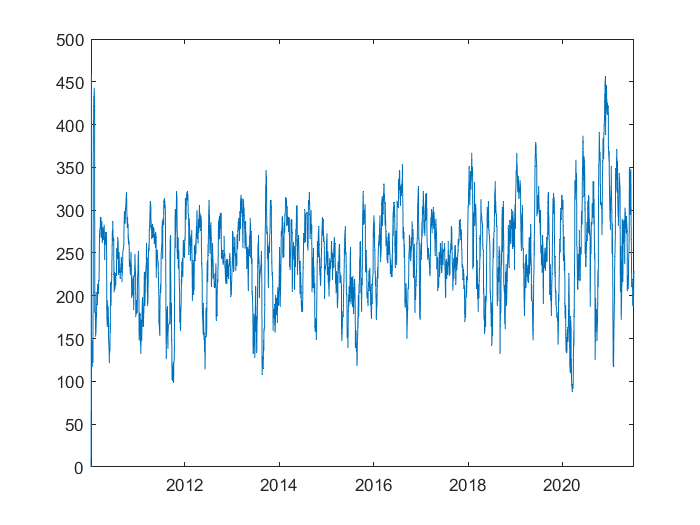


nDailySignal = sum(SMASignalFinal,2) ;
nDailySignalTT = timetable (SMASignalFinalTT.Time, nDailySignal, 'VariableNames',"nDailySignal") ;
plot (nDailySignalTT.Time, nDailySignalTT.Variables )


%Strategy
TradingCosts = 0 * [0.2/100, 0.2/100] ;

SMAInitWeights = [] ;
SMArebalanceFcn = @(w, p, s) RebalanceWeightsFcn(w, p, s) ;
SMAStrategy = backtestStrategy ('SMAStrategyBacktest', SMArebalanceFcn, ...
    'TransactionCosts',TradingCosts, "RebalanceFrequency", 1, ...
    "LookbackWindow", 2, "InitialWeights",SMAInitWeights ) 

SMAStrategy =   backtestStrategy with properties:

                  Name: "SMAStrategyBacktest"
          RebalanceFcn: @(w,p,s)RebalanceWeightsFcn(w,p,s)
    RebalanceFrequency: 1
      TransactionCosts: [0 0]
        LookbackWindow: 2
        InitialWeights: [1×0 double]



%Set-up backtest engine
bt = backtestEngine(SMAStrategy, 'RiskFreeRate', 0.0/365, ...
    "InitialPortfolioValue", 10^2)

bt =   backtestEngine with properties:

               Strategies: [1×1 backtestStrategy]
             RiskFreeRate: 0
           CashBorrowRate: 0
          RatesConvention: "Annualized"
                    Basis: 0
    InitialPortfolioValue: 100
                NumAssets: []
                  Returns: []
                Positions: []
                 Turnover: []
                  BuyCost: []
                 SellCost: []



% run the strategy backtest
startIdx = LagDays ;

bt = runBacktest (bt, PriceTT, SMASignalFinalTT, 'start', startIdx) 

bt =   backtestEngine with properties:

               Strategies: [1×1 backtestStrategy]
             RiskFreeRate: 0
           CashBorrowRate: 0
          RatesConvention: "Annualized"
                    Basis: 0
    InitialPortfolioValue: 100
                NumAssets: 665
                  Returns: [2839×1 timetable]
                Positions: [1×1 struct]
                 Turnover: [2839×1 timetable]
                  BuyCost: [2839×1 timetable]
                 SellCost: [2839×1 timetable]


% Summary
SummaryTable = summary (bt)

SummaryTable = 9×1 table
                       SMAStrategyBacktest
                       ___________________

    TotalReturn                1.7495     
    SharpeRatio              0.068163     
    Volatility              0.0054466     
    AverageTurnover           0.13702     
    MaxTurnover               0.59704     
    AverageReturn          0.00037119     
    MaxDrawdown               0.38725     
    AverageBuyCost                  0     
    AverageSellCost                 0     


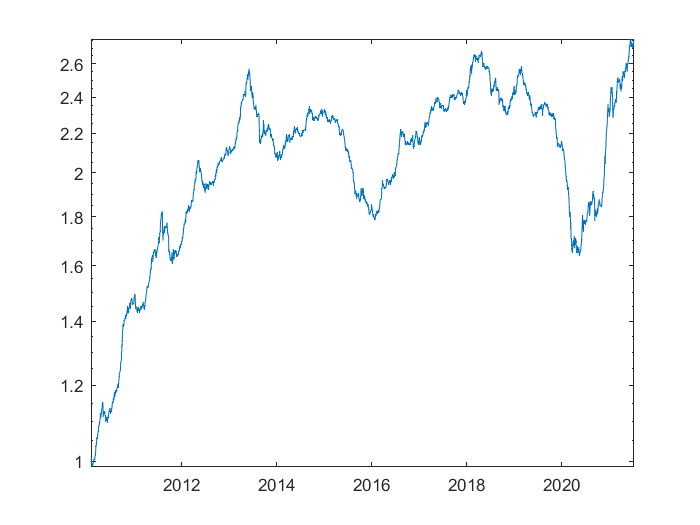

%Plot cumulative return
dailyRet = bt.Returns ;
portfolioValue = ret2tick (dailyRet) ;
% plot (portfolioValue.Time, portfolioValue.Variables)
semilogy(portfolioValue.Time, portfolioValue.Variables)

% equityCurve(bt)

%Asset area plot
time = bt.Positions.SMAStrategyBacktest.Time ;
positions = bt.Positions.SMAStrategyBacktest.Variables ;

Period = yearfrac (time(1), time(end))

Period = 11.4493

PortValue = portfolioValue.Variables ;
portfolioValue (end,:)

ans = 1×1 timetable
       Time        SMAStrategyBacktest
    ___________    ___________________

    09-Jul-2021          2.7495       


CAGR = (PortValue (end))^(1/Period)-1

CAGR = 0.0924

SharpeRatio = sharpe (bt.Returns.Variables,0 )

SharpeRatio = 0.0682

AnnualizedSharpeRatio = sharpe (bt.Returns.Variables,0 )*sqrt(250)

AnnualizedSharpeRatio = 1.0778

[MaxDD,MaxDDIndex] = maxdrawdown(portfolioValue.Variables )

MaxDD = 0.3873

MaxDDIndex =         2032
        2563


AritmeticMeanPrcnt = mean (bt.Returns.Variables)*100

AritmeticMeanPrcnt = 0.0371

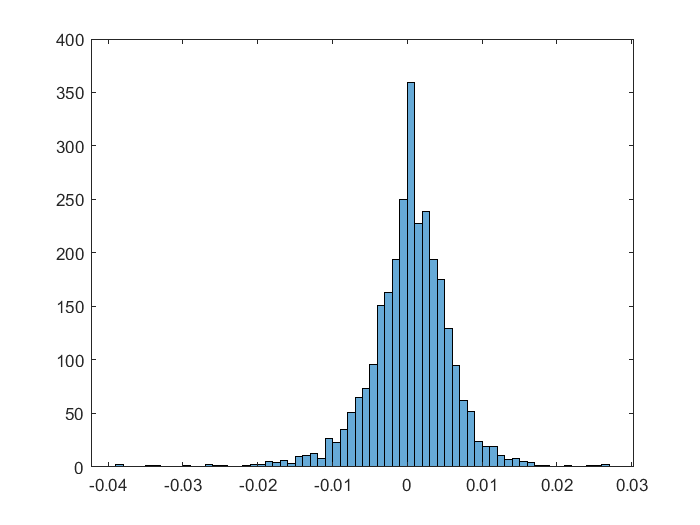

histogram (bt.Returns.Variables)


PositionsTT = bt.Positions.SMAStrategyBacktest 

PositionsTT = 2840×666 timetable
       Time           Cash         ANTM       ANJT       ANDI       AMRT       AMOR      AMIN     AMFG       AMAR      AMAN     AISA       AIMS       AHAP       AGRS       AGRO       AGII       AGAR      ADRO     ADMG       ADMF       ADHI      ADES     ACST      ACES     ABMM      ABDA     ABBA       AALI       AMAG      ALTO     ALMI       ALKA       ALDO      AKSI   

InitialWeightsTT = bt.Strategies.InitialWeights 


InitialWeightsTT =

  1×0 empty double row vector



TurnoverPortfolio = bt.Turnover ;

outputFilename = 'Output3.xlsx' ;
% writetimetable (PositionsTT, outputFilename, 'sheet', "PositionsTT") ;
% writetimetable (SMASignalFinalTT, outputFilename, 'sheet', "SMASignalFinalTT") ;
% writetimetable (PriceTT, outputFilename, 'sheet', "PriceTT") ;
% writematrix (InitialWeightsTT , outputFilename, 'sheet', "InitialWeightsTT") ;


toc

Elapsed time is 32.058500 seconds.


Local functions

function new_weights = RebalanceWeightsFcn (Current_Weights ,PriceTT , SignalTT) 
% Compute weights based on most recent signal.

% Pull out the signal
CrossoverSignal = SignalTT.Variables ;

% Bet sizing
UninvestedAssets = sum (CrossoverSignal(end, :)) ;
 
new_weights = CrossoverSignal(end,:) * (1 / UninvestedAssets) ;


end


function new_weights = equalWeightsFcn (Current_Weights ,PriceTT , SignalTT) 
% Compute weights based on most recent signal.

% Pull out the signal
equalWeightsSignal = SignalTT.Variables ;

% Bet sizing
nAssets = size (CrossoverSignal(end, :)) ;
 
new_weights = CrossoverSignal(end,:) * (1 / nAssets) ;


end
